# Section 1: Create X

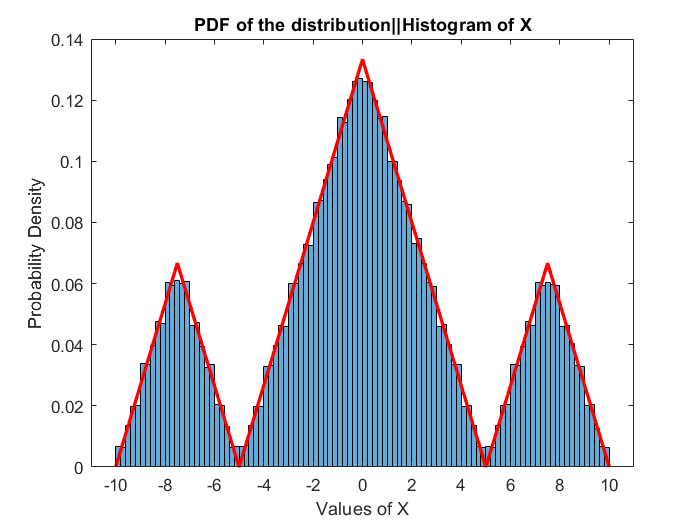

% clearvars;
% clear all;
% close all;
m = 2/75;
x = -10:0.5:10;
x2 = x.^2;
Fx = ((m*(x2/2 + 10*x) + 4/3 ).*rang(x,-10,-7.5)  ) + ((-m*(x2/2 + 5*x)-0.25 + (1/12)).*rang(x,-7.5,-5) ) ...
    + ((m*(x2/2 + 5*x)+(1/3) + (1/6)).*rang(x,-5,0)) + ((-m*(x2/2 - 5*x) + 0.5).*rang(x,0,5)) ...
    + ((m*(x2/2 - 5*x)+(5/6)+(1/3)).*rang(x,5,7.5)) + ((-m*(x2/2 - 10*x)-1.25 + (11/12)).*rang(x,7.5,10)) ;

fx = (m*(x + 10).*rang(x,-10,-7.5)) + (-m*(x + 5).*rang(x,-7.5,-5)) ...
    + (m*(x + 5).*rang(x,-5,0)) + (-m*(x - 5).*rang(x,0,5)) ...
    + (m*(x - 5).*rang(x,5,7.5)) + (-m*(x - 10).*rang(x,7.5,10)) ;

% plot(x,Fx);
N = 1e6 ;
F_dist = makedist('PiecewiseLinear', 'x', x, 'Fx', Fx);
X = random(F_dist, 1, N);
histogram(X, 'Normalization', 'pdf')
hold on
plot(x, fx, 'r', 'LineWidth', 2)
title("PDF of the distribution||Histogram of X");
xlabel("Values of X");
ylabel("Probability Density");

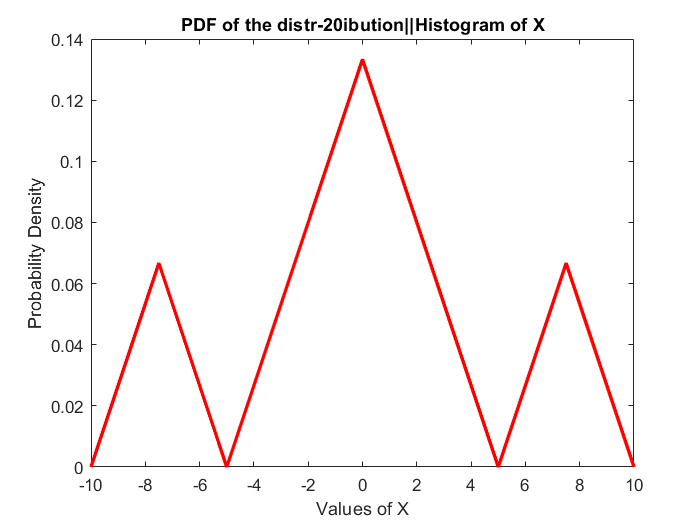

figure;
plot(x, fx, 'r', 'LineWidth', 2)
title("PDF of the distr-20ibution||Histogram of X");
xlabel("Values of X");
ylabel("Probability Density");

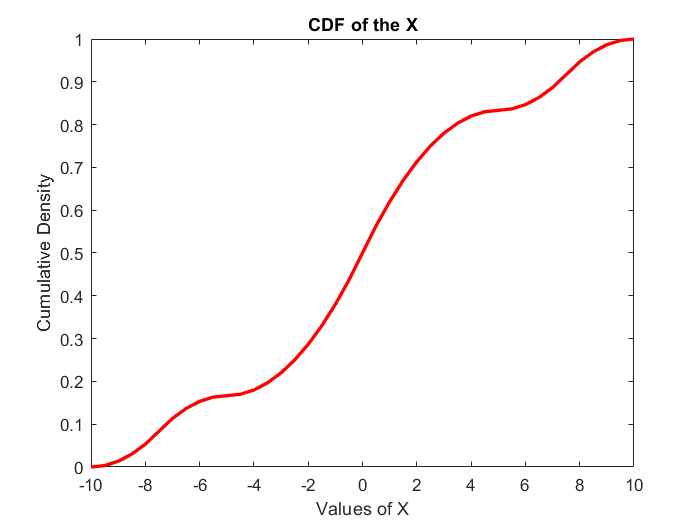


figure;
plot(x, Fx, 'r', 'LineWidth', 2)
title("CDF of the X");
xlabel("Values of X");
ylabel("Cumulative Density");

# Section 2: Create Y

Y = zeros(1,N);
Y(1) = 0;
for i = [2:N]
    Y(i) = X(i) +0.5*X(i-1);
end

# Section 3: Plot Y

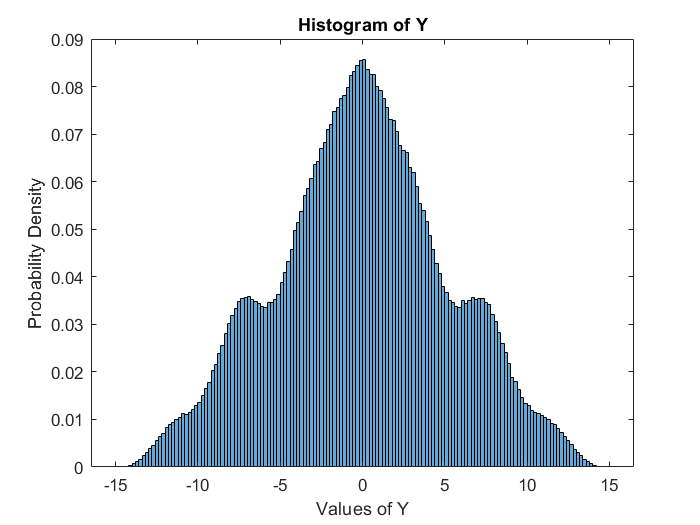

y = -15:0.5:15;
figure;
histogram(Y, 'Normalization', 'pdf')
title("Histogram of Y");
xlabel("Values of Y");
ylabel("Probability Density");

# Section 4: Quantize Y

MSE = 1e-4;
delta = sqrt(12*MSE);
bins = ceil((30)/delta);
[partition,codebook,MSE_calculated] = lloyds(Y,bins); %Max-Lloyd Algorithm

# Section 5: Create list of symbols

[symbols,quantized_sample,distor] = quantiz(Y,partition,codebook);
symbols

symbols =    433   276   219   369   641   440   402   507   304   429   613   698   717   315   306   475   440   454   466   636   507   596   464   627   546   479   206   388   499   669   496   651   550   459   475   358   618   764   441   369   344   402   556   489   368   221   275   162   359   476


# Section 5, calculating TPM for correct entropy

L = length(codebook); %%Number of symbols
TPM = zeros(L,L);
code_count = zeros(1,L);%Store the number of occurences of codes

for i = [1:1:N-1]%%Go over all samples of 
    code_count(symbols(i)+1) = code_count(symbols(i)+1) + 1;
    TPM( symbols(i)+1 , symbols(i+1)+1 ) = TPM( symbols(i)+1 ,symbols(i+1)+1 ) + 1;
end

for i = [1:L]
    for j = [1:L]
        TPM(i,j) = TPM(i,j) /code_count(i);
        if(code_count(i) == 0)
            TPM(i, j) = 0;
        end
        
    end
end

# Section 6: Converting code_count to code probabilities

code_prob = zeros(1,L);
for i = [1:L]
    code_prob(i) = code_count(i)/(N-1);%% Convert to probability
end
sum(code_prob)

ans = 1

# Section 7: Using code_prob as the stationary probabilities

Hx = 0;
for i = [1:L]
    row_sum = 0;
    for j = [1:L]
        if(TPM(i,j)~=0)
            row_sum = row_sum + TPM(i,j) * log2(TPM(i,j));
        end
    end
    Hx = Hx + code_prob(i)*row_sum;
end
Hx = -Hx;
Hx

Hx = 8.6430

# Section 8: Huffman encoding

symbol_list = [0:866];%%These are all the symbols in the vocab
%%We will use this as the probabilities of the symbols
dict = huffmandict(symbol_list,code_prob);

# Section 9: Average bit rate in Huffman encoding

symbol_lengths = zeros(1,length(symbol_list));
for sy = [symbol_list]
    symbol_lengths(sy+1) = length(dict{sy+1,2});
end
avg_length_huff = 0;

for sy = [symbol_list]
    avg_length_huff = avg_length_huff + code_prob(sy+1)*symbol_lengths(sy+1);
end
avg_length_huff

avg_length_huff = 9.3091

# Section 10: LZ77 Encoding

coded = lz77(symbols,867)

function [arr] = rang(x,n1,n2)
%n1 < n2
arr = heaviside(x-n1) - heaviside(x-n2);
end

function [coded] = dictToInt(sourceVirgin, dict)
    for i=1:length(sourceVirgin)
        coded(i) = find(dict == sourceVirgin(i));
    end
end

function [coded] = fixedLengthEncoding(source,numSymbols)
    coded = [];
    len = ceil(log2(numSymbols + 1));
    %for i=1:length(source)
    %    code = de2bi(source(i),len,'left-msb');
    %    coded = [coded,code];   %The exact same thing worked before, but now doesn't, don't know why
        %%code = de2bi(source,len,'left-msb');
    %end
    %We do not require the loop at all.
    code = de2bi(source,len,'left-msb');%generates a matrix where each row is an element of source, each encoded with length len
    coded = [coded,code];   %The exact same thing worked before, but now doesn't, don't know why
    coded = reshape(coded',1,[]);
end

function [coded] = encode(source,searchWin,lookAheadWin,numSymbols)
    coded = [];
    i = 1;
    searchBuff = source(1:min([end,searchWin]));
    temp_code = fixedLengthEncoding(searchBuff,numSymbols);
    coded = [coded,temp_code];
    while i < length(source)
        %startindex = i - searchWin;
        
        %%Initializations
        %if startindex < 1
        %    startindex = 1;
        %end
        
        %if i == 1
        %    searchBuff = [];
        %else
        %    searchBuff = source(startindex,i-1);
        %end
        
        %Calculation of end index of searchwin
        %endindex = min([(i + lookAheadWin -1), length(source)]);
        endsearch = min([i + searchWin - 1], length(source)-1);
        searchBuff = source(i:endsearch);
        endlookAhead = min([endsearch + lookAheadWin,length(source)]);
        lookAheadBuff = source((endsearch+1):endlookAhead);
        u=0;
        n=0;
        %This loop could be run from high to low if a lot of repeatations
        %are being found and small lookAheadBuff, would be better for
        %computation.
        %length(lookAheadBuff)
        for ntemp = 1:length(lookAheadBuff)
           utemp = searchBack(lookAheadBuff,searchBuff,ntemp);  %utemp = -1 if string is not found or 0, check later.
           if utemp ~= -1
               %if utemp != -1 or 0, string of larger length is found,
               %update. 
               n = ntemp;
               u = utemp;
           end
           %n
           %ntemp
        end
        %n is length of the found string. u is the location of string.
        %It is assumed that we will atleast be able to code atleast one
        %element in any case as the window would be large enough to have
        %all the elements already.
        if(u > 0)
            %ulength = ceil(log2(length(searchBuff) + 1));
            ulength = ceil(log2(length(searchBuff)+1));
            ubit = de2bi(u,ulength,'left-msb'); %We reuire least number of bits because
            %ubit = de2bi(u,'left-msb');
            nlength = ceil(log2(n)) + 1;
            %n
            %nlength
            %nbit = de2bi(n,nlength,'left-msb');
            nbit = de2bi(n,'left-msb'); %Automatically returns least required bits
            output = [zeros(1,length(nbit)-1),nbit,ubit];
            i = i + n;
            %n
            %i
            coded = [coded,output];
        else
            %fprintf("Error\n");
            u = length(searchBuff);
            %ulength = ceil(log2(length(searchBuff)+1));
            %ubit = de2bi(u,ulength,'left-msb'); %We reuire least number of bits because
            len = ceil(log2(numSymbols + 1));
            ubit = de2bi(lookAheadBuff(1),len,'left-msb'); %%First element would be the one not present, stored as fixed length coding
            nbit = de2bi(length(lookAheadBuff)+1,'left-msb');%%As the nbit is larger than the maximum look ahead window size, the element could not be found
            output = [zeros(1,length(nbit)-1),nbit,ubit];
            coded = [coded,output];
            i = i+1;
            %printf("Single memeber sent");
            %In case of unavailable code in the search buff, The length
            %given out is max_length_lookAheadBuff + 1. As this is not
            %possible, the decoder would come to know that the next code
            %could not be found in the string
            %Fixed Length code of the corresponding bit is sent as u.
            
        end

    end
end

function [utemp] = searchBack(lookAheadBuff,searchBuff,ntemp)
    k = 0;  %k denotes the element being searched in ntemp
    %ntemp
    for j = length(searchBuff):-1:ntemp
        if(searchBuff(j) == lookAheadBuff(ntemp))
            for i = ntemp:-1:1
                %i
                %index = j - ntemp +i
                if(searchBuff(j-ntemp+i) == lookAheadBuff(i))
                    k = k+1;
                end
            end
            if (k == ntemp)
                utemp = j-ntemp + 1;
                return;
            end
        end
    end
    if k ~=ntemp
        utemp = -1;
        return;
    end
end